# Noise Variances

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_77686 with NodeURI http://sml-OptiPlex-9010:42913/ and MasterURI http://localhost:11311.


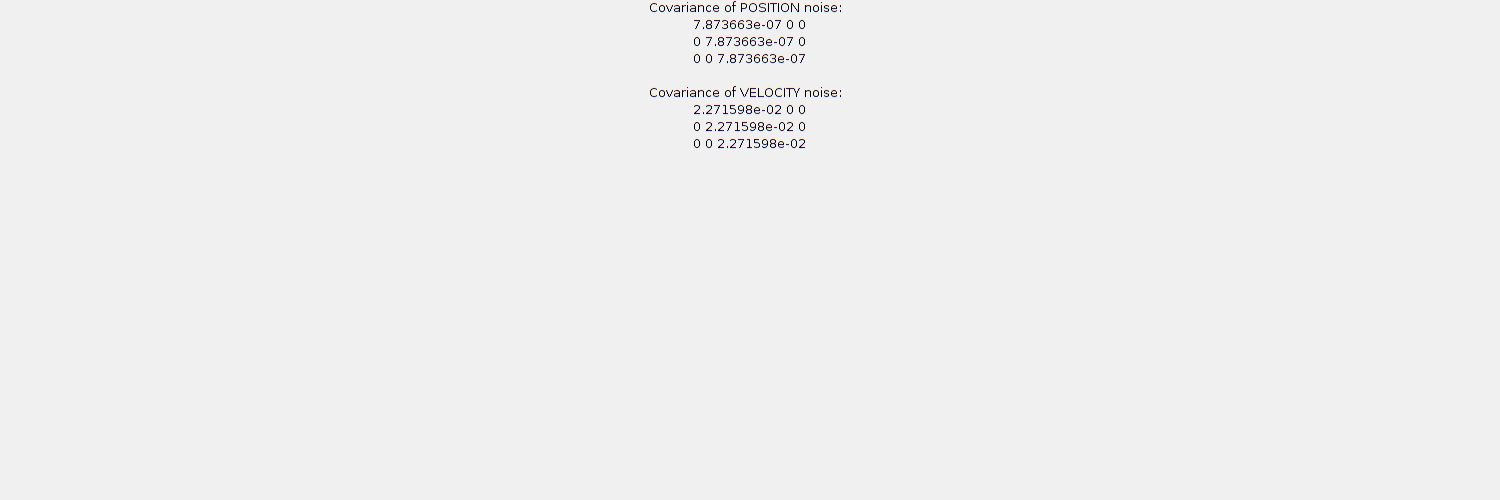

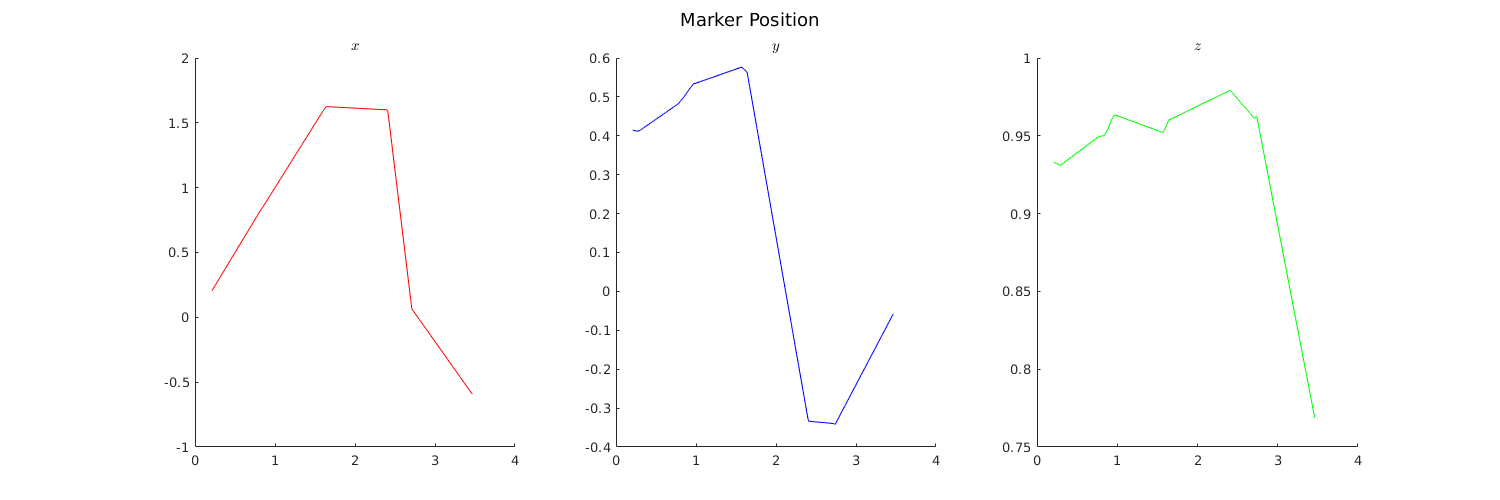

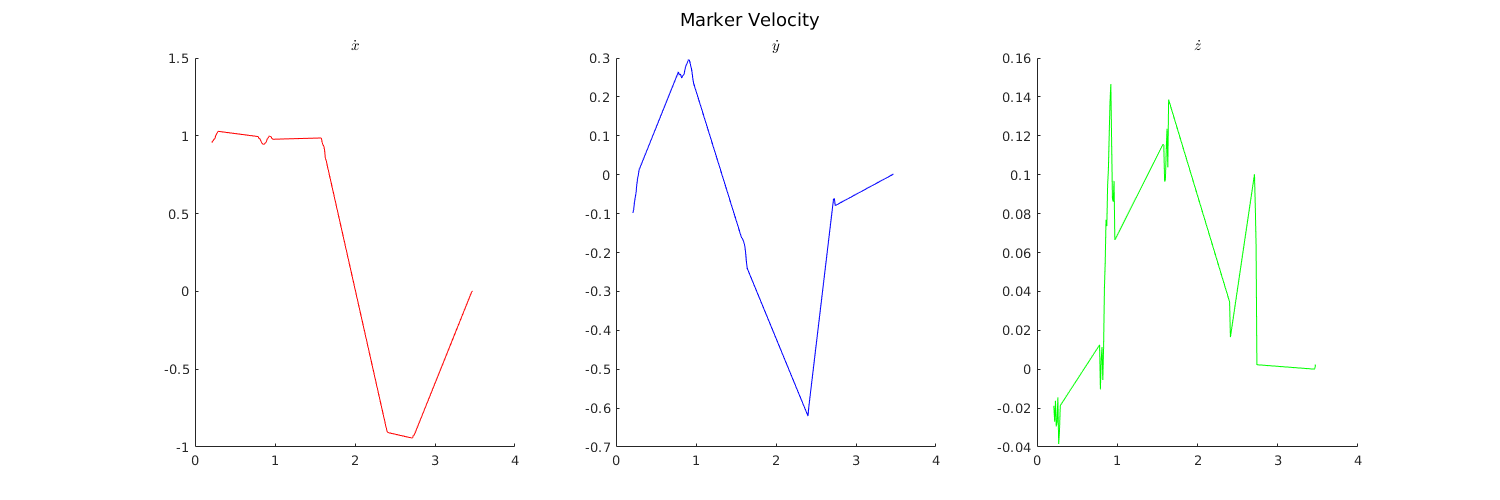

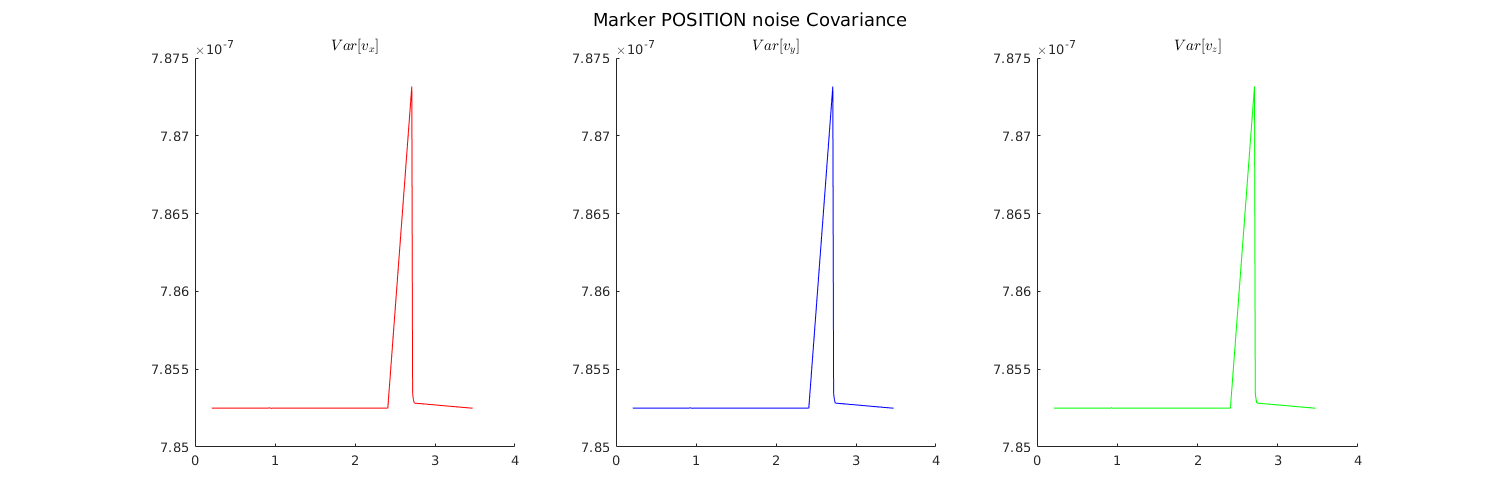

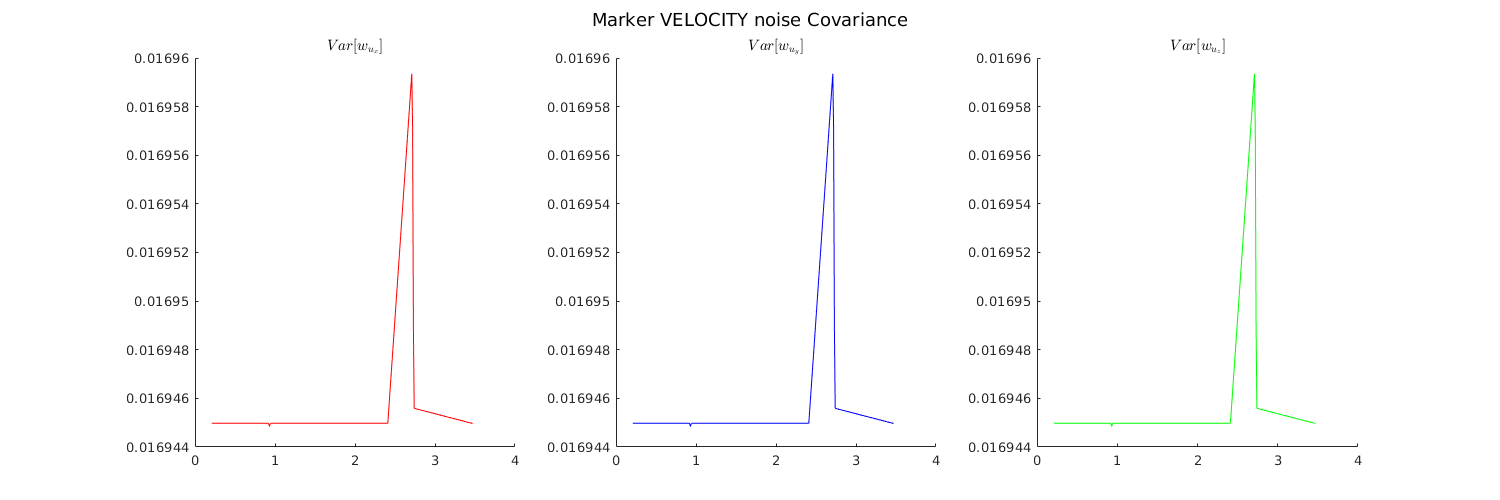

Shutting down global node /matlab_global_node_77686 with NodeURI http://sml-OptiPlex-9010:42913/ and MasterURI http://localhost:11311.


% Run script
run('Noise_estimation.m');

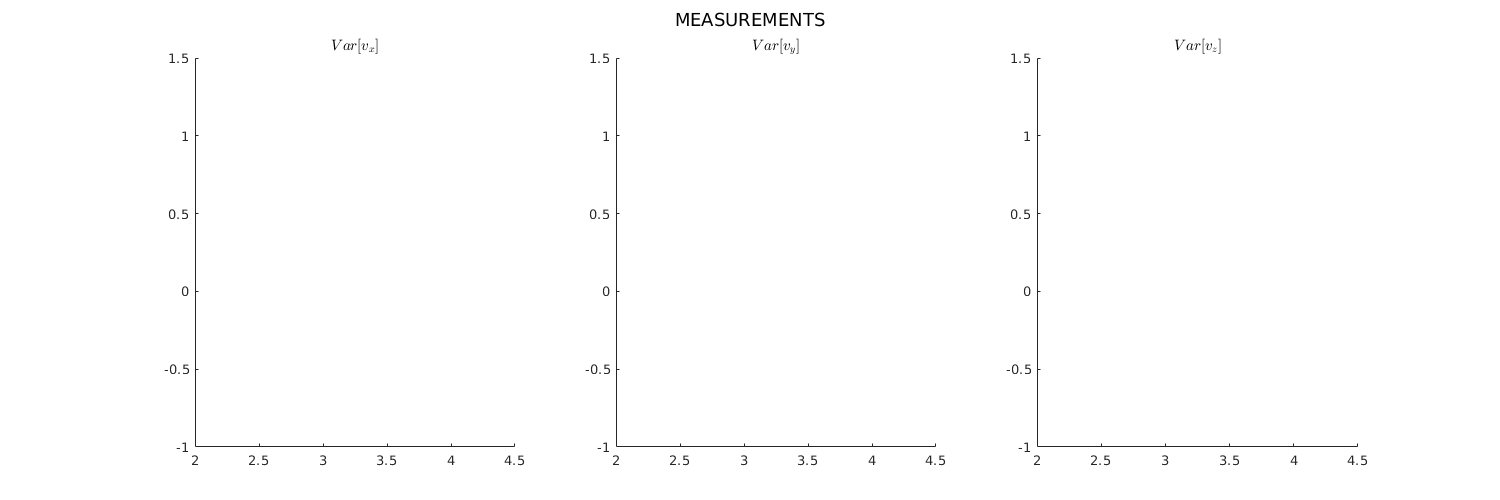

clf;
% Plot data --> Noisy merkers' position and velocity
figure.fig_3 = figure(3);
sgtitle("MEASUREMENTS");

for i = 1 : 3
    
    if (i == 1)

        coordinate_p = '$x$';
        coordinate_v = '$\dot{x}$';
    end

    if (i == 2)

        coordinate_p = '$y$';
        coordinate_v = '$\dot{y}$';
    end

    if (i == 3)

        coordinate_p = '$z$';
        coordinate_v = '$\dot{z}$';
    end

    
    set(fig_100, 'position', [10, 10, 1300, 900]);
    subplot(2,3,i);
    plot(est.super_m1_pos.time, est.super_m1_pos.signals.values(:, i));
    title(coordinate_p, 'Interpreter', 'latex');
    subplot(2,3,i+3);
    plot(est.super_m1_vel.time, est.super_m1_vel.signals.values(:, i));
    title(coordinate_v, 'Interpreter', 'latex');
end

Unrecognized function or variable 'fig_100'.

# Mex functions generation

#### FORWARD KINEMATICS


$$\pmatrix{p_{1} \cr P_{2} \cr .. \cr P_{M}} = \pmatrix{\Phi_1(q) \cr \Phi_2(q) \cr ..  \cr \Phi_M(q) } \qquad \Longrightarrow \qquad  p = \Phi(q)$$


#### JACOBIAN COMPUTATION


$$\pmatrix{\dot{p}_{1} \cr \dot{p}_{2} \cr .. \cr \dot{p}_{M}} = \pmatrix{J_1(q) \cr J_2(q) \cr ..  \cr J_M(q) } \cdot \dot{q} \qquad \Longrightarrow \qquad  \tilde{u} = J(q) \cdot  \dot{q} $$


% % Marker is placed in the : shoulder --> 1
% %                           forearm  --> 2
% %                           hand     --> 3
% marker.links = [1;
%                 2;
%                 3];
% 
% sample_Time = 0.01;
% % Change directory
% cd 'C code/S1_F1_H1/';
% 
% % Run script
% mex_generation(marker.links, sample_Time);
% cd ../..;

# LS APPROACH


$$\dot{q} = J^{\dagger}(q) \cdot  \tilde{u} \qquad \longrightarrow \qquad \tilde{u} = \dot{p}$$


## 1.  PERFECT GUESS OF INITIAL CONDITION q0 

% % Simulation IC [rad]
% simulink.q0 = zeros(n, 1);

% Initial CORRECT joint variables estimate used by LS
LS.q0 = [0;
         0;
         0;
         0;
         0;
         0;
         0];

### 1.1 SMALLER NOISE vs LARGER NOISE affecting pdot

% Noise affecting pdot measurements
noise.input_var = 0.0000001 * ones(m * 3, 1);

% Simulation
output_1 = sim("master_thesis_simulink.slx");

Invalid setting in 'master_thesis_simulink/System/q_eq' for parameter 'Value'.

Caused by:
    Error using master_thesis
    Error evaluating parameter 'Value' in 'master_thesis_simulink/System/q_eq'
        Error using master_thesis
        Unable to resolve the name 'kf.equilibrium_q'.


% Noise affecting pdot measurements
noise.input_var = 0.000001 * ones(m * 3, 1);

% Simulation
output_2 = sim("master_thesis_simulink.slx");

% Plot error between q_LS and q (comparison between smaller noise and larger noise)
title_name = cell(n, 1);
fig_1 = figure(1);
for i = 1 : n

    title_name{i} = strcat('q_', num2str(i), ' - q_', num2str(i), '^{LS}');
    set(fig_1, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_1.q.time, rad2deg(output_1.q.signals.values(:, i) - squeeze(output_1.q_LS.signals.values(i, :))'));
    hold on;
    plot(output_2.q.time, rad2deg(output_2.q.signals.values(:, i) - squeeze(output_2.q_LS.signals.values(i, :))'));
    legend('Smaller noise', 'Larger noise', 'Location', 'southeast');
    title(title_name{i});
end

## 2.  WRONG GUESS OF INITIAL CONDITION q0

% Initial WRONG joint variables estimate used by LS
LS.q0 = [pi/6;
         0;
         0;
         0;
         0;
         0;
         0];

% Noise affecting pdot measurements
noise.input_var = 0.0000001 * ones(m * 3, 1);

% Simulation
output_3 = sim("master_thesis_simulink.slx");

% Plot error between q_LS and q
fig_3 = figure(3);
for i = 1 : n

    title_name{i} = strcat('q_', num2str(i), ' - q_', num2str(i), '^{LS}');
    set(fig_3, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_3.q.time, rad2deg(output_3.q.signals.values(:, i) - squeeze(output_3.q_LS.signals.values(i, :))'));
    legend('error', 'Location', 'southeast');
    title(title_name{i});
end

# KALMAN FILTER ON LINEARIZED DISCRETE STATE-SPACE MODEL

## 1.  Discrete Non Linear model (Ts = 10ms)

Runge-Kutta discretization method is applied to the continuos NL model. The sampling time Ts = 10ms was chosen.


$$\begin{cases}
\mathbf{q}_{k+1} = \textbf{f}(\mathbf{q}_k, \mathbf{u}_k)   \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) 
+  \mathbf{v}_k \\
\end{cases} \qquad , \quad 

\begin{cases}
\mathbf{u}_k \sim \mathcal{N}(0, \mathbf{N_u})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases} \\
\textbf{f} = \mathbf{q}_k + \frac{1}{6}  \cdot T_s  \cdot (\mathbf{k_1} + 2\mathbf{k_2} + 2\mathbf{k_3} + \mathbf{k_4})
\\
\\
\mathbf{k_1} = \mathbf{J}^{\dagger}(\mathbf{q}_k)\cdot \mathbf{u}_k  \\
\mathbf{k_2} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_1}{2})\cdot \mathbf{u}_k  \\
\mathbf{k_3} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_2}{2})\cdot \mathbf{u}_k  \\
\mathbf{k_4} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  k_3)\cdot \mathbf{u}_k$$


The comparison between the simulation and the discrete Non Linear model is reported below.

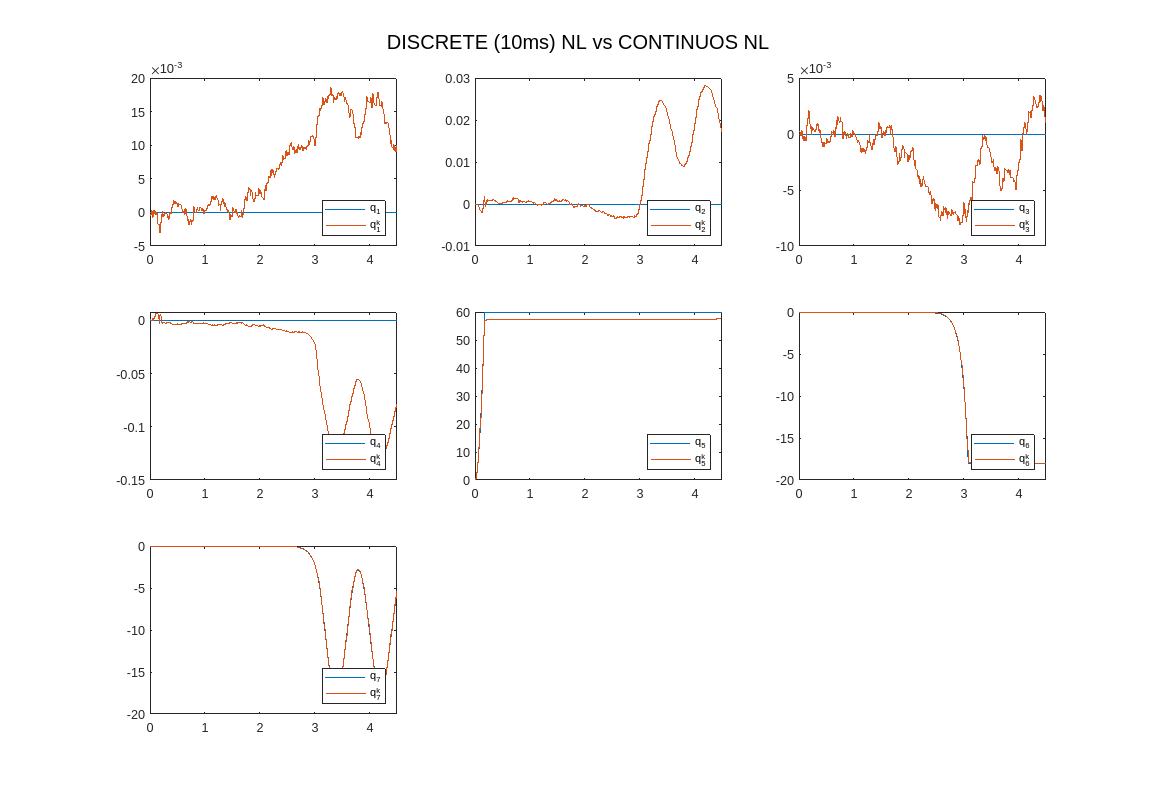

% Simulation
output_4 = sim("master_thesis_simulink.slx");

% Plot DISCRETE vs CONTINUOS joints' variables (q vs qk)
fig_4 = figure(4);
sgtitle("DISCRETE (10ms) NL vs CONTINUOS NL");
for i = 1 : n

    q = strcat('q_', num2str(i));
    qk = strcat('q^k_', num2str(i));
    set(fig_4, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_4.q.time, rad2deg(output_4.q.signals.values(:, i)));
    hold on;
    stairs(output_4.qk.time, rad2deg(squeeze(output_4.qk.signals.values(i, :))'));
    legend(q, qk, 'Location', 'southeast');
end

## 2.  Linearized Discrete model around equilibrium point

The Discrete state-space model is computed by linearizing the discrete NL model around a given equilibrium point.                                                


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta u}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot\mathbf{\Delta q}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad 
\begin{cases}
\mathbf{\Delta q}_{k} = \mathbf{q}_k - \mathbf{q}_{eq} \\
\mathbf{\Delta u}_{k} = \mathbf{u}_k - \mathbf{u}_{eq} \\
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


where,


$$\\
\mathbf{F} = \nabla_q\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{G} = \nabla_u\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{H} = \nabla_q\mathbf{\Phi}|_{q_{eq}}$$


In the following 2 examples (in which the human arm motion is different as well as the equilibrium point) $$q^{lin}_i$$ referes to the linearized state $i$.

### 2.1 Free fall motion, eq. point (q_eq = 0, u_eq = 0)

The discrete NL model, linearized around the equilibrium point q_eq = 0, u_eq = 0, is expected to simulate very poorly the human arm free fall motion.

The comparison between simulation and linearized discrete state-space is reported below.

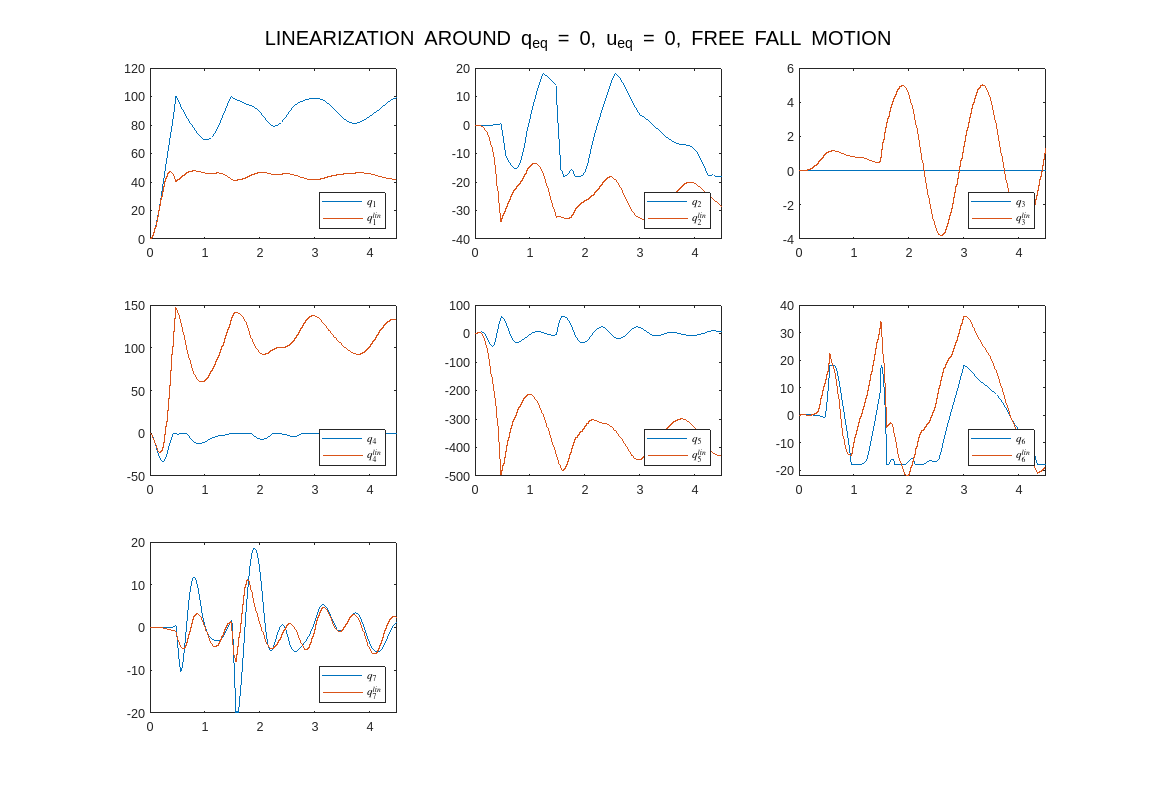

% Linearized Discrete model 'on'
set_param('master_thesis_simulink/System/Linearized Discrete Model', 'commented', 'off');

% Human Arm IC SIMULATION
simulink.q0 = zeros(n, 1);

% Joints' trajectory
% q1
set_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'TorqueActuationMode', 'NoTorque', 'MotionActuationMode', 'ComputedMotion');

% q2
set_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_roty', 'TorqueActuationMode', 'NoTorque', 'MotionActuationMode', 'ComputedMotion');


% q3
set_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'TorqueActuationMode', 'NoTorque', 'MotionActuationMode', 'ComputedMotion');

% q4
set_param('master_thesis_simulink/System/Human arm/Elbow_joint/jRightElbow_rotx', 'TorqueActuationMode', 'NoTorque', 'MotionActuationMode', 'ComputedMotion');

% Equilibrium point
kf.equilibrium_q = zeros(n, 1);
kf.equilibrium_u = zeros(3*m, 1);

% F matrix --> df/dq evaluated at the equilibrium point q_eq = 0, u_eq = 0
kf.F = full(functions.f_Fekf(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, kf.equilibrium_u));
% G matrix --> df/du evaluated at the equilibrium point q_eq = 0, u_eq = 0
kf.G = full(functions.f_Gekf(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, kf.equilibrium_u));

% H matrix --> dPhi/dq (Jacobian J) evaluated at the equilibrium point q_eq = 0
kf.H = full(functions.f_J(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables));
% J matrix --> dPhi/du = 0 
kf.J = zeros(3*m, 3*m);

% Discrete State-Space model IC
kf.q0 = simulink.q0;

% Simulation
output_5 = sim("master_thesis_simulink.slx");

% Plot DISCRETE LINEARIZED vs CONTINUOS joints' variables (q vs qklin)
fig_5 = figure(5);
sgtitle("LINEARIZATION AROUND q_{eq} = 0, u_{eq} = 0, FREE FALL MOTION");
for i = 1 : n

    q = strcat('$q_', num2str(i), '$');
    qk = strcat('$q^{lin}_', num2str(i), '$');
    set(fig_5, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_5.q.time, rad2deg(output_5.q.signals.values(:, i)));
    hold on;
    stairs(output_5.qk_lin.time, rad2deg(squeeze(output_5.qk_lin.signals.values(i, :))'));
    legend(q, qk, 'Location', 'southeast', 'Interpreter', 'latex');
end

### 2.2 Human arm motion close to the rest position

The discrete NL model is now linearized around the rest position of the human arm, i.e. when the human arm is perpendicular to the ground.

In this context all initial joints' variables are assumed to be set to 0°, except for $q_1$ which is set to 87°.


$$q_0 = \pmatrix{87\degree  \cr 0\degree  \cr ..  \cr 0\degree } , \qquad q_{eq} =  \pmatrix{90 \degree  \cr 0\degree  \cr ..  \cr 0\degree },  \qquad u_{eq} =  \pmatrix{ 0  \cr 0  \cr ..  \cr 0 } $$


The model is now expected to simulate better the human arm motion.

The comparison between simulation and linearized discrete state-space is reported below.

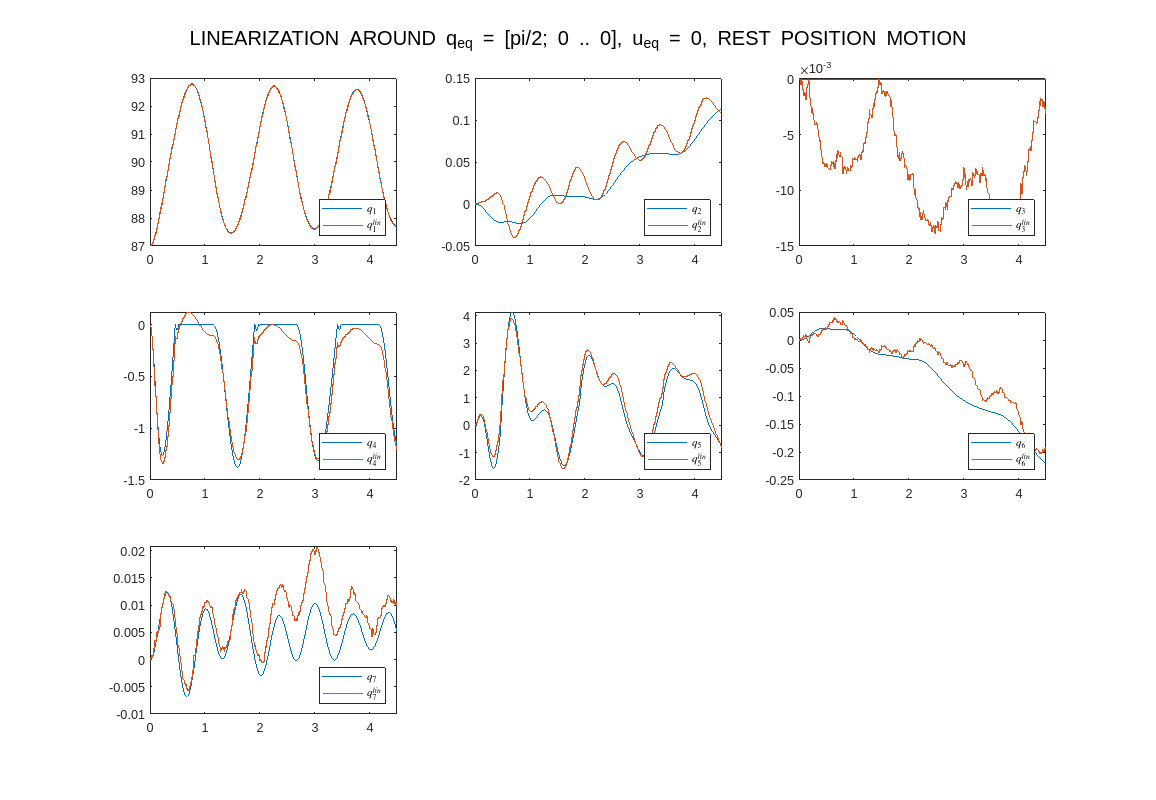

% Linearized Discrete model 'on'
set_param('master_thesis_simulink/System/Linearized Discrete Model','commented','off');

% Human Arm IC SIMULATION [rad]
simulink.q0 = [deg2rad(87); zeros(n-1, 1)];

% Equilibrium point
kf.equilibrium_q = [pi/2; zeros(n-1, 1)];
kf.equilibrium_u = zeros(3*m, 1);

% F matrix --> df/dq evaluated at the equilibrium point q_eq = pi/2, u_eq = 0
kf.F = full(functions.f_Fekf(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, kf.equilibrium_u));
% G matrix --> df/du evaluated at the equilibrium point q_eq = pi/2, u_eq = 0
kf.G = full(functions.f_Gekf(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, kf.equilibrium_u));

% H matrix --> dPhi/dq (Jacobian J) evaluated at the equilibrium point q_eq = pi/2
kf.H = full(functions.f_J(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables));
% J matrix --> dPhi/du = 0 
kf.J = zeros(3*m, 3*m);

% Discrete State-Space model IC
kf.q0 = simulink.q0;

% Simulation
output_6 = sim("master_thesis_simulink.slx");

% Plot DISCRETE LINEARIZED vs CONTINUOS joints' variables (q vs qklin)
fig_6 = figure(6);
sgtitle("LINEARIZATION AROUND q_{eq} = [pi/2; 0 .. 0], u_{eq} = 0, REST POSITION MOTION");
for i = 1 : n

    q = strcat('$q_', num2str(i), '$');
    qk = strcat('$q^{lin}_', num2str(i), '$');
    set(fig_6, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_6.q.time, rad2deg(output_6.q.signals.values(:, i)));
    hold on;
    stairs(output_6.qk_lin.time, rad2deg(squeeze(output_6.qk_lin.signals.values(i, :))'));
    legend(q, qk, 'Location', 'southeast', 'Interpreter', 'latex');
end

## 3.  Kalman Filter on the linearized discrete state-space model

The Discrete state-space model is computed by linearizing the discrete NL model around the given equilibrium point.                                              


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta u}_k + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot \mathbf{\Delta q}_k + \mathbf{v}_k \\
\end{cases} \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


Since $\mathbf{G}\cdot \mathbf{\Delta u}_k = \mathbf{G}\cdot (\mathbf{u}_k - \mathbf{u}_{eq}) $, it follows that


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G_{-}}\cdot \mathbf{u}_{eq} + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot \mathbf{\Delta q}_k + \mathbf{v}_k \\
\end{cases} \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


with 

$\mathbf{G_{-}} = - \mathbf{G}$, 


$$\mathbf{Q} = \mathbf{G}\cdot\mathbf{N_u}\cdot\mathbf{G^T}$$


A full-order state observer was implemented to estimate the states but it **does not** remove the noise affecting the measurement.

As a first simulation, the human arm motion close to its rest position is considered.

clf;
% Uncomment State-Observer
set_param('master_thesis_simulink/System/State-observer','commented','off');

% Consider example 2.2
% Human Arm IC SIMULATION [rad]
simulink.q0 = [deg2rad(87); zeros(n-1, 1)];

% Equilibrium point
kf.equilibrium_q = [pi/2; zeros(n-1, 1)];
kf.equilibrium_u = zeros(3*m, 1);

% F matrix --> df/dq evaluated at the equilibrium point q_eq, u_eq = 0
kf.F = full(functions.f_Fekf(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, kf.equilibrium_u));
% G matrix --> df/du evaluated at the equilibrium point q_eq, u_eq = 0
kf.G = full(functions.f_Gekf(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, kf.equilibrium_u));

% H matrix --> dPhi/dq (Jacobian J) evaluated at the equilibrium point q_eq = 0
kf.H = full(functions.f_J(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables));
% J matrix --> dPhi/du = 0 
kf.J = zeros(3*m, 3*m);

% Set initial condition
kf.q0 = simulink.q0;

% NLDM IC
set_param('master_thesis_simulink/System/NLDM delay', 'InitialCondition', 'kf.q0');

% Design of a full order state-observer
state_observer.obs_matrix = obsv(kf.F, kf.H);
if (rank(state_observer.obs_matrix) == n)
    disp("The pair (F, H) is observable");
    state_observer.eigs = zeros(n, 1);
    state_observer.L = place(kf.F', -kf.H', state_observer.eigs)';
end

The pair (F, H) is observable


### Kalman Filter parameters

I assume $\mathbf{\Delta q}_0 = \mathbf{0}$, $\mathbf{P}_0 = \pmatrix{10 & 0 & .. & ..\cr 0 & 10 & .. & .. \cr .. & .. & .. & ..\cr .. & .. & .. & 10} $

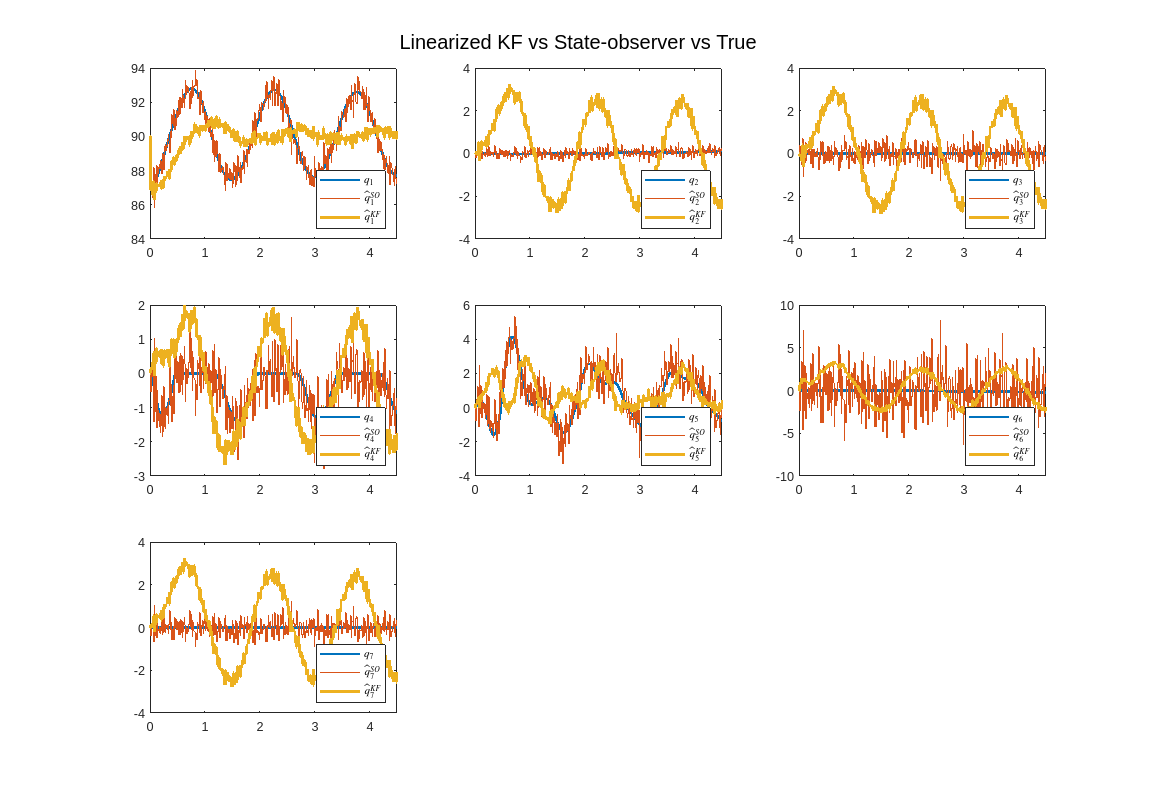

% Kalman filter function 'on'
set_param('master_thesis_simulink/System/Kalman Filter','commented','off');

% Input covariance matrix
% kf.Nu = diag(noise.input_var);

% Process covariance matrix
% kf.Q = kf.G * kf.Nu * kf.G';
kf.Q = diag(noise.process_var);

% Measurement covariance matrix
kf.R = 10e-2 * diag(noise.measurement_var);

% Initial state estimate Delta_q0
kf.x0est = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 10 * eye(n);

% List of Pk for k = 1, .., N
kf.Pk = [kf.P0];
% List of Pk_ for k = 1, .., N
kf.Pk_ = [];
% List of Kk for k = 1, .., N
kf.Kk = [];

% Compute Pk, Pk_, Kk offline
for k = 1 : simulink.time/sample_Time

    Pk_ = kf.F * kf.Pk(1:n, n*(k-1)+1:n*(k-1)+n) * kf.F' + kf.Q;
    Kk = Pk_ * kf.H' / (kf.H * Pk_ * kf.H' + kf.R);
    Pk = (eye(n) - Kk * kf.H) * Pk_ * (eye(size(kf.F, 1)) - Kk * kf.H)' + Kk * kf.R * Kk';
    kf.Pk_ = [kf.Pk_, Pk_];
    kf.Kk = [kf.Kk, Kk];
    kf.Pk = [kf.Pk, Pk];

end

% Simulation
output_7 = sim("master_thesis_simulink.slx");

% Plot KF estimate vs CONTINUOS joints' variables
fig_7 = figure(7);
sgtitle("Linearized KF vs State-observer vs True");

for i = 1 : n

    q = strcat('$q_', num2str(i), '$');
    qso = strcat('$\hat{q}^{SO}_', num2str(i), '$');
    qkf = strcat('$\hat{q}^{KF}_', num2str(i), '$');
    set(fig_7, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_7.q.time, rad2deg(output_7.q.signals.values(:, i)), 'LineWidth', 2);
    hold on;
    stairs(output_7.qk_state_obs.time, rad2deg(squeeze(output_7.qk_state_obs.signals.values(i, :))'));
    hold on;
    stairs(output_7.qk_kf.time, rad2deg(squeeze(output_7.qk_kf.signals.values(i, :))'), 'LineWidth', 2);
    legend(q, qso, qkf, 'Location', 'southeast', 'Interpreter', 'latex');
end

# EXTENDED KALMAN FILTER

## 1.  Discrete Non Linear model


$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


We perform a Taylor series expansion of the state equation around $\mathbf{q}_{k-1} = \hat{\mathbf{q}}_{k-1}^+$ and we obtain:


$$\mathbf{q}_{k} = \mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1}\right) + \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =
\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)+\mathbf{F}_{k-1}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =

\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\left[\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)-\mathbf{F}_{k-1} \hat{\mathbf{q}}_{k-1}^{+}\right] + \mathbf{w}_{k-1} \\ =
\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\mathbf{r}_{k-1}+\mathbf{w}_{k-1}$$


We linearize the measurement equation around $\mathbf{q}_k = \hat{\mathbf{q}}_k^-$ and we obtain:


$$\mathbf{p}_{k} = \mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \mathbf{H}_{k}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{H}_{k}\mathbf{q}_{k}+\left[\mathbf{\Phi}\left(\hat{\mathbf{q}}_{k}^{-}\right)-\mathbf{H}_{k}\hat{\mathbf{q}}_{k}^{-}\right]+\mathbf{v}_k \\ =
\mathbf{H}_{k} \mathbf{q}_{k}+\mathbf{z}_{k}+\mathbf{v}_{k}$$
				

We can use the standard Kalman Filter equations to estimate the state.

In summary, the following steps are performed to compute the KF estimate at each step.

- The system and measurement equations are given as follows 

          
$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


- Initialize the filter as follows  $\hat{\mathbf{q}}_{0}^+ = \mathbb{E}(\mathbf{q}_0) \quad, \quad
\mathbf{P}_0^+ = \mathbb{E}[(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)^T]$ 

- For k = 1, 2, .. perform the following 

                          
$$\mathbf{F}_{k-1} =  \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+},\mathbf{u}_{k-1}
\\
\mathbf{G}_{k-1} =  \left.\frac{\partial \mathbf{f}}{\partial \mathbf{u}}\right|_{\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}$$


                            **TIME UPDATE**

                            
$$\mathbf{P}_k^- = \mathbf{F}_{k-1}\mathbf{P}_{k-1}^+\mathbf{F}_{k-1}^T + \mathbf{Q} \\
\hat{\mathbf{q}}_k^- = \mathbf{f}(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1})$$


                             
$$\mathbf{H}_{k} =  \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}$$


                            **MEASUREMENT UPDATE**

                            
$$\mathbf{K}_k = \mathbf{P}_{k}^-\mathbf{H}_{k}^T(\mathbf{H}_k\mathbf{P}_k^-\mathbf{H}_k^T + \mathbf{R})^{-1}
\\
\hat{\mathbf{q}}_k^+ = \hat{\mathbf{q}}_k^- + \mathbf{K}_k[\textbf{p}_k - \mathbf{\Phi}(\hat{\mathbf{q}}_k^-)]
\\
\mathbf{P}_k^+ = (\mathbf{I} - \mathbf{K}_k\mathbf{H}_k)\mathbf{P}_k^-$$


A new example is now considered.

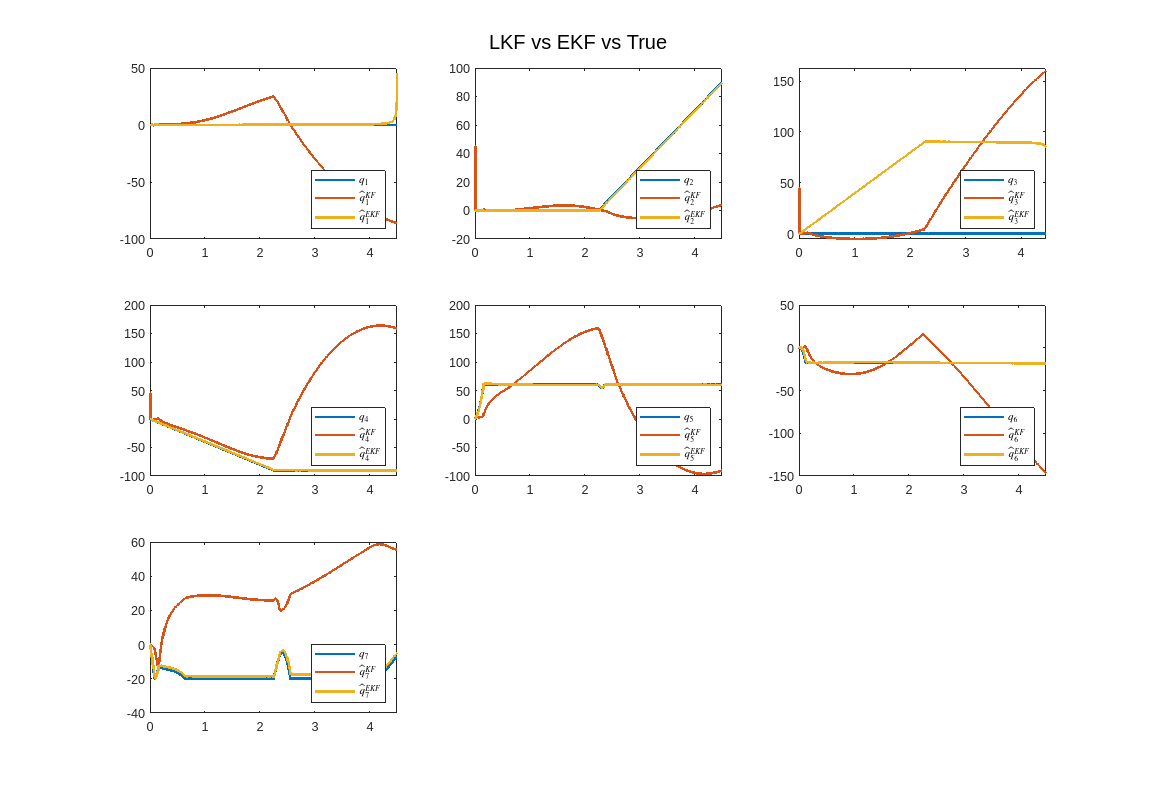

clf;
% Human Arm IC SIMULATION [rad]
simulink.q0 = zeros(n, 1);

% Joints' trajectory
% q1
set_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
add_line('master_thesis_simulink/System/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'PortHandles').LConn(2));
%delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'PortHandles').LConn(2));

% q2
set_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_roty', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
add_line('master_thesis_simulink/System/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/c2', 'PortHandles').RConn, get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_roty', 'PortHandles').LConn(2));
%delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c2', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_roty', 'PortHandles').LConn(2));

% q3
set_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
add_line('master_thesis_simulink/System/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/c3', 'PortHandles').RConn, get_param('master_thesis_simulink/System/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'PortHandles').LConn(2));
%delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c3', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'PortHandles').LConn(2));

% q4
set_param('master_thesis_simulink/System/Human arm/Elbow_joint/jRightElbow_rotx', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
add_line('master_thesis_simulink/System/Human arm/Elbow_joint', get_param('master_thesis_simulink/System/Human arm/Elbow_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/System/Human arm/Elbow_joint/jRightElbow_rotx', 'PortHandles').LConn(2));
%delete_line('master_thesis_simulink/Human arm/Elbow_joint', get_param('master_thesis_simulink/Human arm/Elbow_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/Elbow_joint/jRightElbow_rotx', 'PortHandles').LConn(2));

%
%% LINEARIZED KALMAN FILTER
%

% Equilibrium point
kf.equilibrium_q = [0; pi/4; pi/4; pi/4; zeros(n-4, 1)];
kf.equilibrium_u = zeros(3*m, 1);

% F matrix --> df/dq evaluated at the equilibrium point q_eq, u_eq = 0
kf.F = full(functions.f_Fekf(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, kf.equilibrium_u));
% G matrix --> df/du evaluated at the equilibrium point q_eq, u_eq = 0
kf.G = full(functions.f_Gekf(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, kf.equilibrium_u));

% H matrix --> dPhi/dq (Jacobian J) evaluated at the equilibrium point q_eq = 0
kf.H = full(functions.f_J(kf.equilibrium_q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables));
% J matrix --> dPhi/du = 0 
kf.J = zeros(3*m, 3*m);

% Set initial condition
kf.q0 = simulink.q0;

%kf.Nu = diag(noise.input_var);

% Process covariance matrix
%kf.Q = kf.G * kf.Nu * kf.G';
kf.Q = diag(noise.process_var);

% Measurement covariance matrix
kf.R = 10e-5 * diag(noise.measurement_var);

% Initial state estimate Delta_q0
kf.x0est = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 1 * eye(n);

% List of Pk for k = 1, .., N
kf.Pk = [kf.P0];
% List of Pk_ for k = 1, .., N
kf.Pk_ = [];
% List of Kk for k = 1, .., N
kf.Kk = [];

% Compute Pk, Pk_, Kk offline
for k = 1 : simulink.time/sample_Time

    Pk_ = kf.F * kf.Pk(1:n, n*(k-1)+1:n*(k-1)+n) * kf.F' + kf.Q;
    Kk = Pk_ * kf.H' / (kf.H * Pk_ * kf.H' + kf.R);
    Pk = (eye(n) - Kk * kf.H) * Pk_ * (eye(size(kf.F, 1)) - Kk * kf.H)' + Kk * kf.R * Kk';
    kf.Pk_ = [kf.Pk_, Pk_];
    kf.Kk = [kf.Kk, Kk];
    kf.Pk = [kf.Pk, Pk];

end

%
%% EXTENDED KALMAN FILTER
%

% Extended Kalman Filter 'on'
set_param('master_thesis_simulink/System/Extended Kalman Filter','commented','off');

% Set initial condition
ekf.q0 = simulink.q0;

% NLDM IC
set_param('master_thesis_simulink/System/NLDM delay', 'InitialCondition', 'ekf.q0');

% Process covariance matrix
% ekf.Nu = diag(noise.input_var);
ekf.Q = diag(noise.process_var);

% Measurement covariance matrix
ekf.R = 10e-2 * diag(noise.measurement_var);

% Initial state estimate Delta_q0
ekf.q0est = zeros(n, 1);

% Initial covariance estimate P0
ekf.P0 = 1 * eye(n);

% Simulation
output_8 = sim("master_thesis_simulink.slx");

% Plot KF estimate vs EKF estimate
fig_8 = figure(8);
sgtitle("LKF vs EKF vs True");

for i = 1 : n

    q = strcat('$q_', num2str(i), '$');
    qkf = strcat('$\hat{q}^{KF}_', num2str(i), '$');
    qekf = strcat('$\hat{q}^{EKF}_', num2str(i), '$');
    set(fig_8, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_8.q.time, rad2deg(output_8.q.signals.values(:, i)), 'LineWidth', 2);
    hold on;
    stairs(output_8.qk_kf.time, rad2deg(squeeze(output_8.qk_kf.signals.values(i, :))'), 'LineWidth', 2);
    hold on;
    stairs(output_8.qk_ekf.time, rad2deg(squeeze(output_8.qk_ekf.signals.values(i, :))'), 'LineWidth', 2);
    legend(q, qkf, qekf, 'Location', 'southeast', 'Interpreter', 'latex');
end

% Uncomment joints' trajectory
% q1
% set_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
% add_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'PortHandles').LConn(2));
% delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c1', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotx', 'PortHandles').LConn(2));

% q2
% set_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_roty', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
% add_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c2', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_roty', 'PortHandles').LConn(2));
% delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c2', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_roty', 'PortHandles').LConn(2));

% q3
% set_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'TorqueActuationMode', 'ComputedTorque', 'MotionActuationMode', 'InputMotion');
% add_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c3', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'PortHandles').LConn(2));
% delete_line('master_thesis_simulink/Human arm/RightShoulder_joint', get_param('master_thesis_simulink/Human arm/RightShoulder_joint/c3', 'PortHandles').RConn, get_param('master_thesis_simulink/Human arm/RightShoulder_joint/jRightShoulder_rotz', 'PortHandles').LConn(2));